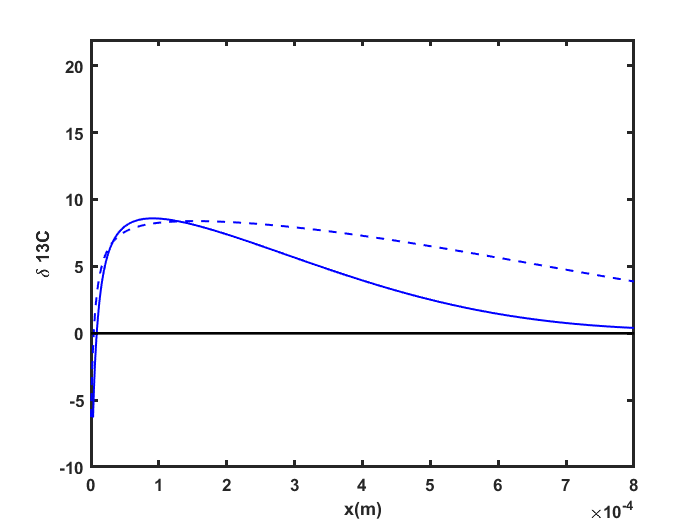

plot(x(1:end-99),mymod(100:end),'b-','LineWidth',1.2);
hold on
plot(x(1:end-13),oldmod(1:end-12),'b--','LineWidth',1.2);
%plot([step(r) step(r)],[0.01085 0.01125],'--','color',[1 0 0])
%grid;
plot(x,zeros(length(x)),"k",'LineWidth',1.6)
%plot([step(r) step(r)],[0.01085 0.01125],'--','color',[1 0 0])
axis([0,0.0008,-10,22]);
h=gca;
%legend;
% legendCell = cellstr(num2str(step1', '%2.3f days'));
% legend(legendCell);
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x(m)');
ylabel('\delta 13C');

print(gcf,'modelcompa.png','-dpng','-r330');
hold off